# **Thermal Analysis for New and Aged Battery Packs**

This example shows how to evaluate a new and end-of-life (EOL) lithium-ion battery pack. With cell usage and time, the capacity of the cell degrades and the resistance increases due to the formation of a solid-electrolyte-interface (SEI), a passivation layer over the anode surface. You must design battery pack components to meet warranty criteria at EOL time from power, performance, and packaging perspectives. This example analyzes a 400V battery pack for EOL thermal performance based on its packaging.

## Build Battery Pack

To build the battery pack used in this example, follow the steps in the [Build Model of Battery Pack with Cell Aging](docid:battery_ug#example-batt_build_battery_pack_cell_aging) example and generate the `batt_PackCellAgingModelLib` SLX file in your working directory. This SLX file contains the battery pack model for cell aging applications. This battery pack comprises five module assemblies. Each module assembly comprises five modules. Each battery module has 12 cells. The EOL for the battery pack is equal to 1000 cycles. 

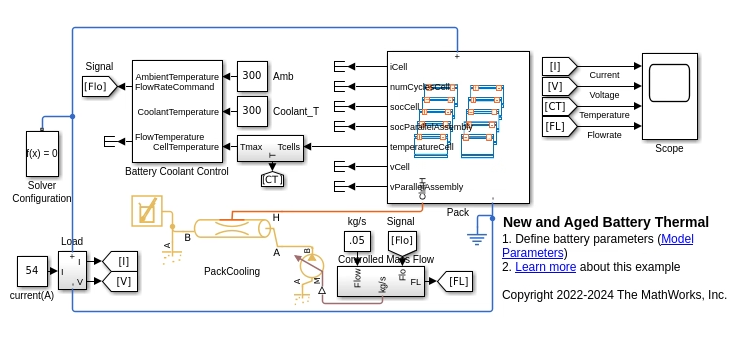

A Pipe block cools the battery pack modules and the Battery Coolant Control block controls the coolant flowrate. To analyze the worst case scenario, the circuit receives a constant 2C-rate current of 54 A for 30 minutes.

## Define Parameters and Run Simulations

Initialize the battery parameters. At the MATLAB® Command Window, enter:

run("batt_PackCellAgingModel_param");

Simulate a new battery pack for a constant discharging current at 2C rate.

batt_PackCellAgingModelData = sim("batt_PackCellAgingModelSim");
% Post-process data
newPack_Temp = batt_PackCellAgingModelData.batt_PackCellAgingResults.get("Temperature").Values.Data;
newPack_Time = batt_PackCellAgingModelData.batt_PackCellAgingResults.get("Temperature").Values.Time;
newPack_Volt = batt_PackCellAgingModelData.batt_PackCellAgingResults.get("Voltage").Values.Data;
newPack_Curr = batt_PackCellAgingModelData.batt_PackCellAgingResults.get("Current").Values.Data;
newPack_Flow = batt_PackCellAgingModelData.batt_PackCellAgingResults.get("Flowrate").Values.Data;

Simulate an EOL battery pack. Every 100 cycles, the **Terminal Resistance, R0** parameter of the cell decreases by 5%. In each module, set the **Change in terminal resistance after N discharge cycles (%)** parameter to 5 and the **Number of discharge cycles, N** parameter to 100.

ModuleType1.N0Cell = 100;
ParallelAssemblyType1.N0Cell = 100;
ModuleType1.dR0Cell = 5;
ParallelAssemblyType1.dR0Cell = 5;

The thermal resistance of the battery pack, between the cells and the cooling system, degrades with time. The value of the thermal resistance increases from 1.2 for the new pack to 5 for the aged pack.

ModuleType1.CoolantThermalPathResistance = 5;
ParallelAssemblyType1.CoolantThermalPathResistance = 5;

Initialize the battery pack close to the EOL cycle (999).

end_of_life_cycles = 999;
run("batt_PackCellAgingModel_param_EOL")

Simulate the EOL battery pack for a constant discharging current at 2C rate.

batt_PackCellAgingModelData = sim("batt_PackCellAgingModelSim");
% Post-process data
agedPack_Temp = batt_PackCellAgingModelData.batt_PackCellAgingResults.get("Temperature").Values.Data;
agedPack_Time = batt_PackCellAgingModelData.batt_PackCellAgingResults.get("Temperature").Values.Time;
agedPack_Volt = batt_PackCellAgingModelData.batt_PackCellAgingResults.get("Voltage").Values.Data;
agedPack_Curr = batt_PackCellAgingModelData.batt_PackCellAgingResults.get("Current").Values.Data;
agedPack_Flow = batt_PackCellAgingModelData.batt_PackCellAgingResults.get("Flowrate").Values.Data;

## Analyze Results

Load the `batt_PackWithCellBalancingResults` MAT file and run the `batt_PackWithCellBalancingPlot` file. At the MATLAB Command Window, enter: 

max_temp_diff = round(max(squeeze(agedPack_Temp))-max(squeeze(newPack_Temp)),1);
disp(['Battery EOL maximum cell temperature is around ',num2str(max_temp_diff),...
    ' degree Celsius higher than the maximum cell temperature in a new pack.'])

Battery EOL maximum cell temperature is around 5.4 degree Celsius higher than the maximum cell temperature in a new pack.


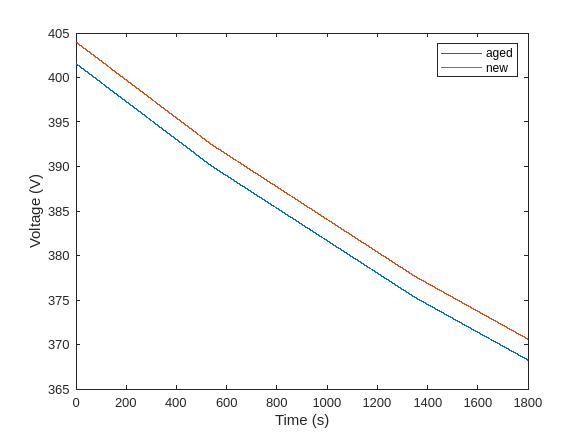

figure(1)
plot(agedPack_Time,squeeze(agedPack_Volt));hold on;
plot(newPack_Time,squeeze(newPack_Volt));hold off;
legend('aged','new','Location','northeast')
ylabel('Voltage (V)')
xlabel('Time (s)')

For the aged cells, the maximum cell temperature is almost 7 degree Celsius higher than the maximum cell temperature of a new pack. The voltage of the aged pack is slightly lower than the voltage of the new pack. These values show that the battery pack design is thermally safe from EOL perspective. 

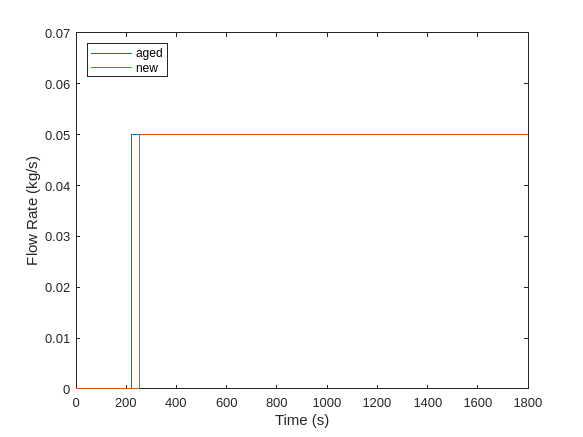

figure(2)
plot(agedPack_Time,squeeze(agedPack_Flow));hold on;
plot(newPack_Time,squeeze(newPack_Flow));hold off;
legend('aged','new','Location','northwest')
ylabel('Flow Rate (kg/s)')
xlabel('Time (s)')
ylim([0 0.07])

This plot shows the coolant flow switch-on times for a new and an aged battery pack. Inside the aged battery pack, as the cells heat up more than in a new battery pack, the battery controller switches on the coolant pump earlier. The pump power consumption is higher due to the earlier activation of the coolant pump.

## Results from Real-Time Simulation

This example has been tested on a Speedgoat Performance real-time target machine with an Intel(R) 3.5 GHz i7 multi-core CPU. This model can run in real time with a step size of 40 milliseconds.

*Copyright 2022-2024 The MathWorks, Inc.*